# this is a test demo for function @filteringfunc

close all;  clear;   clc;
%  DEBUG ! ! !
dbstop if error;
format long

add funtion path. 

% addpath ../include/model_dataprocessing ..\include\model_eventdetection
addpath(genpath('../../../include'));

Select a file path ...    

% filename = '..\..\testdata\strainMat17.mat';
% filename = '..\..\testdata\strainMat61.mat';
filename = '..\..\testdata\strainMat44.mat';
% filename = '..\..\testdata\strainMat103.mat';

import data. 

strainMat = importdata(filename);
[lenPosition,  lenTime] = size(strainMat);
position = 1:lenPosition;     time = (1:lenTime)*0.064;

 a 3D figure of original signal.     

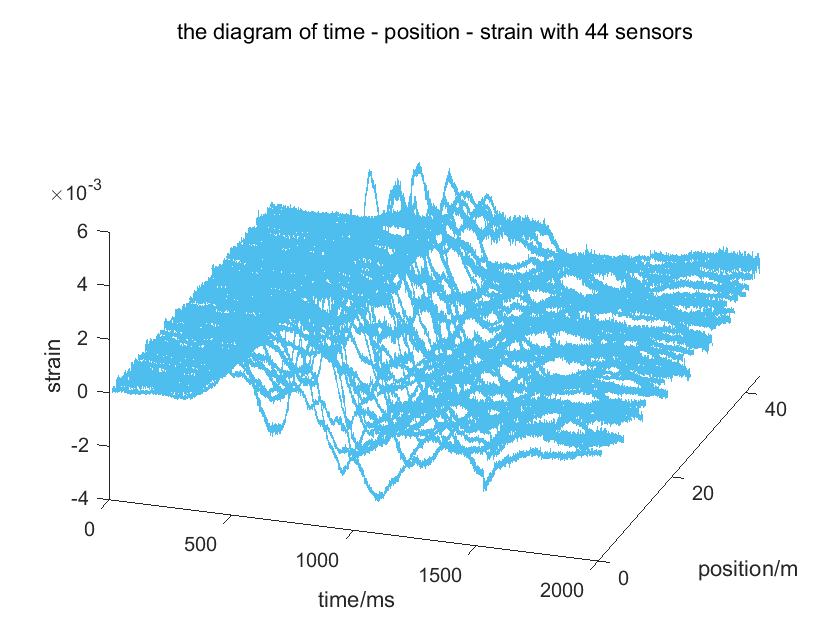

ax1 = axes(figure);
plot3D(ax1, strainMat, position, time);     view(ax1, [18.30400 36.08133])

 lowpass filter.

fp.wp = 20.0;  fp.ws = 40;

 bandpass filter.

% fp.wp = [4, 60];  fp.ws = [1, 100];

 passband ripple, and stopband attenuation.

fp.rp = 1;    fp.rs = 30;
disp('filtering seismic data ... ');

filtering seismic data ... 


filter type:  ftype = 'low' | 'high' | 'band'；

ftype = ' '; % default low or band pass filter.
[strainMat1, timeLagArray, maxCorrArray] = filteringfunc(strainMat, time, fp, ftype);


 a 3D figure of the filtered signal

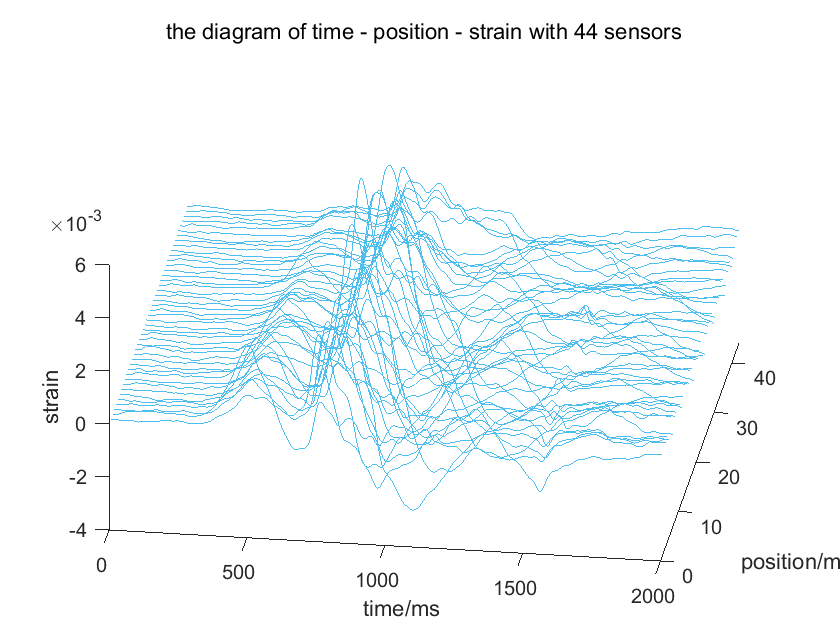

ax2 = axes(figure);
plot3D(ax2, strainMat1, position, time);  view(ax2, [8.10400 39.68483])

- Compare the signal characteristics before and after filtering

num = ceil(lenPosition/10);
strain0 = strainMat(num, :);

disp(['  # ', num2str(num), ' filtering seismic data ... ']);

  # 5 filtering seismic data ... 


[strain1, timelag, maxCorr] = filteringfunc(strain0, time, fp, ftype);
%
[val0, idx0] = max(strain0);      [val1, idx1] = max(strain1);
std0 = std(strain0);                  std1 = std(strain1);
ssnorm = norm(strain0 - strain1);
fprintf('  signal       maxvalue      location        std \n');

  signal       maxvalue      location        std 


fprintf(' original     %2.8f       %5d      %2.8f \n', val0,  idx0, std0);

 original     0.00345676       11457      0.00091081 


fprintf(' filtered     %2.8f       %5d      %2.8f \n', val1,  idx1, std1);

 filtered     0.00337338       11878      0.00090934 


fprintf('  norm2:  %2.8f;   time-lag: %5d;   maxcorr: %2.8f \n', ssnorm, timelag, maxCorr);

  norm2:  0.06159096;   time-lag:  -416;   maxcorr: 0.99609518 


- Compare the signal correlation before and after filtering

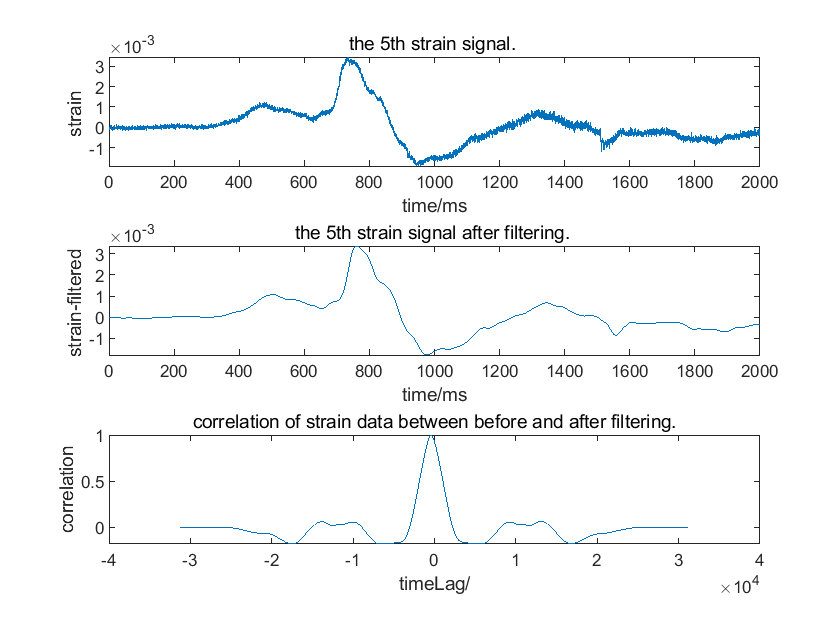

figure;
subplot(311);
plot(time, strain0);
xlabel('time/ms');    ylabel('strain ');
title(['the ', num2str(num), 'th ', 'strain signal. ']);
subplot(312);
plot(time, strainMat1(num, :));
xlabel('time/ms');     ylabel('strain-filtered ');
title(['the ', num2str(num), 'th ', 'strain signal after filtering. ']);
subplot(313);
xcorrArray = crosscorrelation(strain0, strain1);
xcorrTime = (1 : length(xcorrArray)) - length(strain0) - 1;
plot(xcorrTime, xcorrArray); xlabel('timeLag/');  ylabel('correlation');
title('correlation of strain data between before and after filtering.');